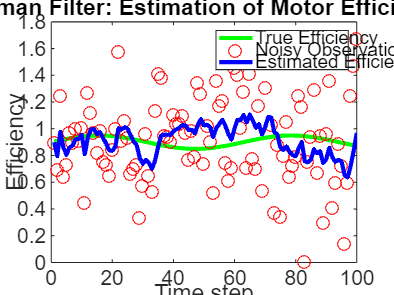

% Load the MotorCAD example
openExample('simscapeelectrical/EfficiencyMapFromMotorCADExample')

% Time settings
dt = 0.1;   % time step
T = 100;    % total time steps

% State Transition Matrix (A) for constant rate of change of efficiency
A = [1 dt;
    0 1];

% Process Noise Covariance (Q)
Q = [0.001 0;
    0 0.001];

% Measurement Noise Covariance (R)
R = 0.1; % Uncertainty in efficiency measurements

% Observation Matrix (H)
H = [1 0];  % We only observe efficiency, not its rate of change

% Initial state estimate (efficiency; rate_of_change_of_efficiency)
x = [0.9; 0];  % Starting with an initial guess for efficiency

% Initial error covariance (P)
P = eye(2); 

% Generate synthetic data for true efficiency and noisy observations
true_efficiency = 0.9 + 0.05 * sin(0.1 * (1:T));  % True efficiency (for illustration)
observed_efficiency = true_efficiency + sqrt(R) * randn(1, T);  % Noisy observations

% Kalman Filter for estimating efficiency
estimated_efficiency = zeros(1, T);

for t = 1:T
    % Prediction step
    x = A * x;  % State prediction (constant rate of change)
    P = A * P * A' + Q;  % Error covariance prediction
    
    % Kalman Gain calculation
    K = P * H' / (H * P * H' + R);
    
    % Measurement update step
    z = observed_efficiency(t);  % Current noisy observation (efficiency)
    x = x + K * (z - H * x);  % State update with observation
    P = (eye(2) - K * H) * P;  % Error covariance update
    
    % Store the estimated efficiency
    estimated_efficiency(t) = x(1);
end

% Plot the results
figure;
plot(1:T, true_efficiency, '-g', 'LineWidth', 2); hold on;
plot(1:T, observed_efficiency, 'ro');
plot(1:T, estimated_efficiency, '-b', 'LineWidth', 2);
legend('True Efficiency', 'Noisy Observations', 'Estimated Efficiency');
title('Kalman Filter: Estimation of Motor Efficiency');
xlabel('Time step');
ylabel('Efficiency')